# Sample 3-4

## 平滑化／先鋭化処理

順序統計フィルタ 

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Image smoothing/sharpening

Oder statistic filter

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### サンプル画像の準備

(Preparation of sample image)

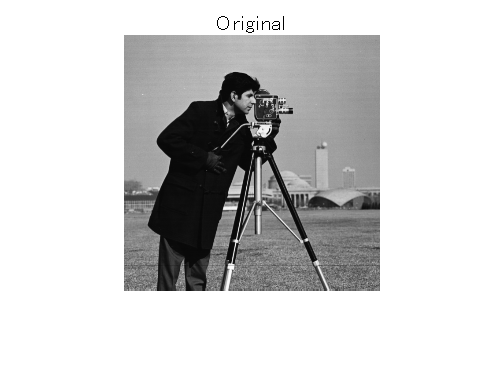

close
% Reading original image
I = im2double(imread('cameraman.tif'));
figure(1)
imshow(I)
title('Original')

### ゴマ塩ノイズ画像の準備

(Preparation of a contaminated image with salt & pepper noise)

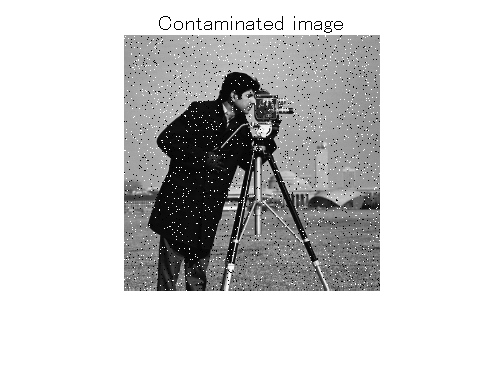

% Density
d = 0.05;
% Add noise
J = imnoise(I,'salt & pepper',d);

% Show the result
figure(2)
imshow(J)
title('Contaminated image')

### 中央値フィルタ

(Median filter)

% Domain size setting 
hsize = 3

hsize = 3

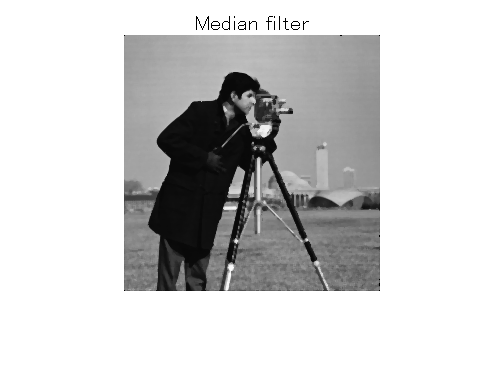

% Median fltering
K = medfilt2(J,[hsize hsize]);

% Show the result
figure(3)
imshow(K)
title('Median filter')

### 最大値フィルタ

(Maximum filter)

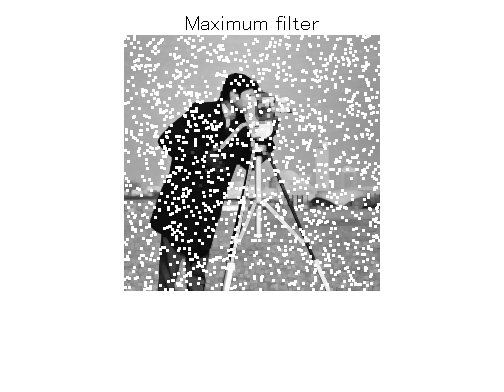

% Domain setting
hsize = 3;
domain = ones(hsize);

% Maximum filtering
L = ordfilt2(J,nnz(domain),domain);

% Show the result
figure(4)
imshow(L)
title('Maximum filter')

### 最小値フィルタ

(Minumum filter)

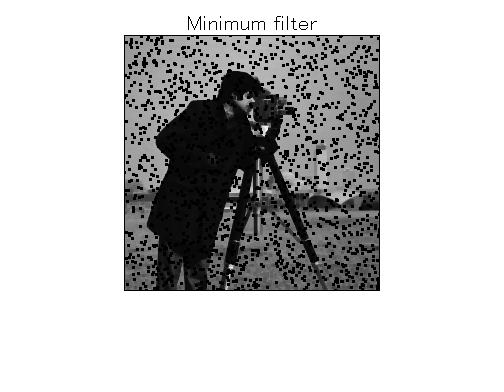

% Domain setting
hsize = 3;
domain = ones(hsize);

% Minimum filtering
M = ordfilt2(J,1,domain);

% Show the result
figure(5)
imshow(M)
title('Minimum filter')

© Copyright, Shogo MURAMATSU, All rights reserved.